Split the table into variable tim and qF

%load data from R-Script "Convert to matlab.R"
load('matlab_all_Experiment.mat')
dF_traces = dF_traces

dF_traces =     0.4328    0.4312    0.4296    0.4278    0.4261    0.4243    0.4226    0.4205    0.4185    0.4162    0.4137    0.4111    0.4085    0.4060    0.4036    0.4013    0.3988    0.3961    0.3934    0.3908    0.3881    0.3853    0.3825    0.3796    0.3767    0.3739    0.3709    0.3679    0.3649    0.3618    0.3588    0.3558    0.3530    0.3502    0.3474    0.3445    0.3418    0.3391    0.3364    0.3338    0.3314    0.3291    0.3270    0.3248    0.3228    0.3209    0.3191    0.3174    0.3158    0.3143
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0       

%Plot data
[rows, cols] = size(dF_traces)

rows = 20

cols = 4500

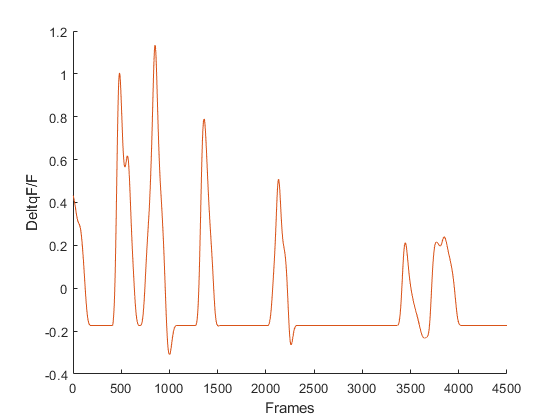

tracks = 1

tracks = 2

tracks = 3

tracks = 4

tracks = 5

tracks = 6

tracks = 7

tracks = 8

tracks = 9

tracks = 10

tracks = 11

tracks = 12

tracks = 13

tracks = 14

tracks = 15

tracks = 16

tracks = 17

tracks = 18

tracks = 19

tracks = 20

figure
hold on
for i = 1:rows
        tracks = i
        plot(dF_traces(tracks,:))
        hold on
        plot(dF_traces(tracks,:))
        xlabel("Frames")
        ylabel("DeltqF/F")
        nexttile
end

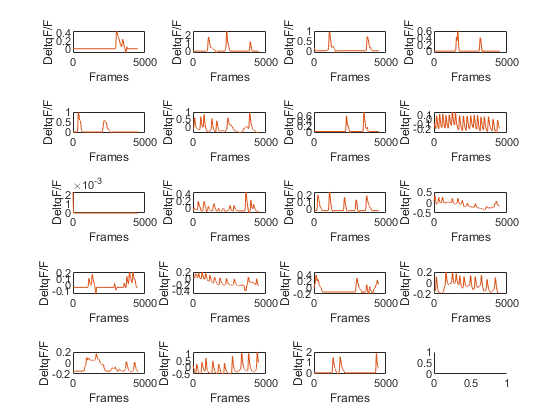

hold off

Processing all columns and detect spikes and interspike intervals

rows = height(dF_traces)

rows = 20

for i = 1: rows
    track = dF_traces(i,:);
    m = quantile(track, 0.8) % can be adjusted to the data

    % Find local maxima 
    pks = islocalmax(track,"MinProminence",m,"MinSeparation",0);
  
    Extrema(:,i) = pks
    
    [pks, locs] = findpeaks(track,'MinPeakProminence',m, "MinPeakDistance",0);
    peakInterval=diff(locs);
   
    len = length(peakInterval)
    Interval(1:len,i) =  peakInterval  
 
    end

m = 0.1520

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 5

Interval =          369         412        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         289        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 3

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.2017

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 2

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0447

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 2

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 2

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0044

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 1

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.1076

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 7

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 7

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0130

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 17

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 0

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0210

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 11

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0363

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 4

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0152

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 10

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0314

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 6

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0155

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 12

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0352

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 5

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0351

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 10

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0457

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 4

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.1426

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 9

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

m = 0.0578

Extrema = 4500×20 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


len = 2

Interval =          369          99        1242         245          84        1797         432         109         209           0         284         807         265         225         214         134         660         674         357         494
         508         412        1612        2382        1542           0         219        1104         216           0         400        1039         251        1548         242        2711         439        1304         274        2514
         773         289           0           0           0           0         537         193         222           0         292         808         407         677         241         669         262         780         470           0
        1313           0           0           0           0           0         336           4         224           0         381         735         273         180         298         211         246         569         400           0
         404           0 

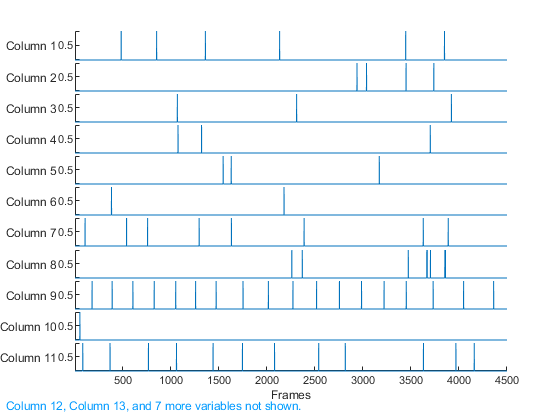

%Visualize data
figure
stackedplot(Extrema)%plot data
xlabel("Frames")

%Plot data: detected spikes together with input data
[rows, cols] = size(Extrema)

rows = 4500

cols = 20

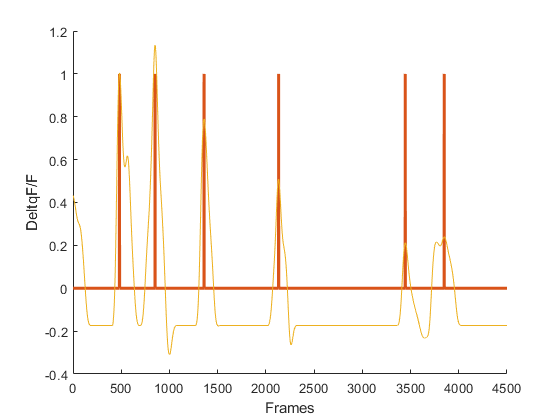

tracks = 1

tracks = 2

tracks = 3

tracks = 4

tracks = 5

tracks = 6

tracks = 7

tracks = 8

tracks = 9

tracks = 10

tracks = 11

tracks = 12

tracks = 13

tracks = 14

tracks = 15

tracks = 16

tracks = 17

tracks = 18

tracks = 19

tracks = 20

figure
hold on
for i = 1:cols
        tracks = i
        plot(dF_traces(tracks,:))
        hold on
        plot(Extrema(:,tracks),'LineWidth',2)
        plot(dF_traces(tracks,:))
        xlabel("Frames")
        ylabel("DeltqF/F")
        nexttile
end

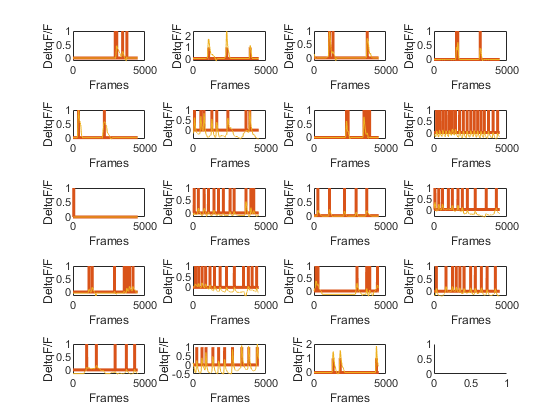

hold off

h1 = struct with fields:
    Binwidth: 500


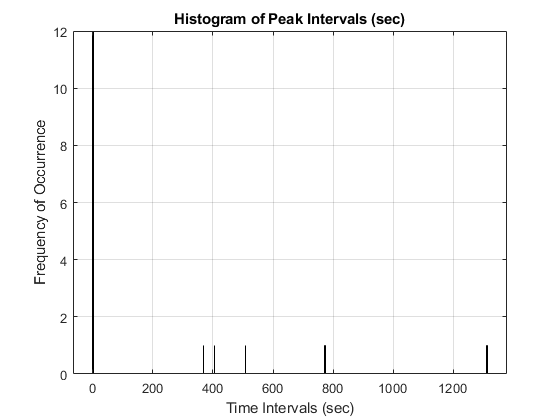

%Save file as csv
Extrema = array2table(Extrema)

writetable(Extrema, "extrema_predictions_matlab_all_Experiment.csv","Delimiter",";")

Extrema = 4500×20 table
    Extrema1    Extrema2    Extrema3    Extrema4    Extrema5    Extrema6    Extrema7    Extrema8    Extrema9    Extrema10    Extrema11    Extrema12    Extrema13    Extrema14    Extrema15    Extrema16    Extrema17    Extrema18    Extrema19    Extrema20
    ________    ________    ________    ________    ________    ________    ________    ________    ________    _________    _________    _________    _________   

Interval = array2table(Interval)
writetable(Interval, "interval_predictions_matlab_all_Experiment.csv","Delimiter",";")

Interval = 57×20 table
    Interval1    Interval2    Interval3    Interval4    Interval5    Interval6    Interval7    Interval8    Interval9    Interval10    Interval11    Interval12    Interval13    Interval14    Interval15    Interval16    Interval17    Interval18    Interval19    Interval20
    _________    _________    _________    _________    _________    _________    _________    _________    _________    __________    __________    __________  